# Diagram of signal processing  

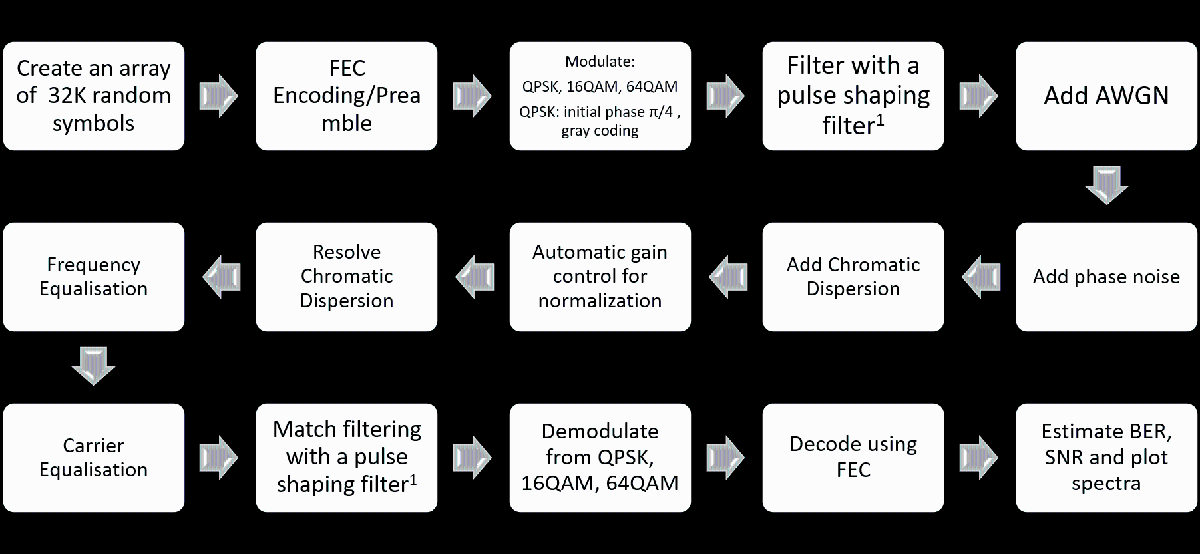

## Constants and Initial Conditions

%Resetting the rng seed
rng("default");
rng(1960);

enable_FEC = false;
enable_pulse_shaping = false;
enable_AWGN = false;
enable_phase_noise = false;
enable_chromatic_dispersion = false;
enable_frequency_equal = false;
enable_carrier_equal = false;


num_symbols = 32*1024; 
symbol_rate = 100e9;
time_step = 1/symbol_rate;
linewidth = 100e3;
variance = 2*pi*linewidth*time_step;

## Forward Error Correction

if enable_FEC
    symbols_b = zeros(1,num_symbols);
    symbols_q = zeros(1,num_symbols);
    symbols_16 = zeros(1,num_symbols);
    symbols_64 = zeros(1,num_symbols);
end
%To be Implemented

## Modulation

%BPSK
M = 2;
if (~enable_FEC)
symbols_b = randi([0 M-1],1,num_symbols);
end
bpsk_mod = pskmod(symbols_b,M,0,'gray');


%QPSK
M = 4;
if (~enable_FEC)
symbols_q = randi([0 M-1],1,num_symbols);
end
qpsk_mod = pskmod(symbols_q,M,pi/M,'gray');


%16QAM
M = 16;
if (~enable_FEC)
symbols_16 = randi([0 M-1],1,num_symbols);
end
qam16_mod = pskmod(symbols_16,M,pi/M,'gray');


%64QAM
M = 64;
if (~enable_FEC)
symbols_64 = randi([0 M-1],1,num_symbols);
end
qam64_mod = pskmod(symbols_64,M,pi/M,'gray');

%{
figure
subplot(2,2,1,gca);
plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
title("BPSK Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
xlim([-1,1]);
ylim([-1,1]);
grid on;
subplot(2,2,2);
grid on;
plot(qpsk_mod,'*','MarkerEdgeColor','black','MarkerFaceColor',"black");
title("QPSK Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
subplot(2,2,3);
plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
title("16 QAM Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
subplot(2,2,4);
plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
title("64 QAM Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
title("Modulated Symbols");
grid on;
%}

## Pulse Shaping and Upconverting

if enable_pulse_shaping
    
end

## AWGN

if enable_AWGN
    
end

## Phase Noise

if enable_phase_noise
    
end

## Chromatic Dispersion

if enable_chromatic_dispersion
    
end

## Chromatic Dispersion Compensation

if enable_chromatic_dispersion
    %Automatic Gain Control here first
end

## Frequency Equalisation

if enable_frequency_equal
    
end

## Carrier Equalisation

if enable_carrier_equal
    
end

## Matched Filter and Downconverting

if enable_pulse_shaping
    
end

## Demodulation

%BPSK
M = 2;
bpsk = pskdemod(bpsk_mod,M,0,'gray');


%QPSK
M = 4;
qpsk = pskdemod(qpsk_mod,M,pi/M,'gray');


%16QAM
M = 16;
qam16 = pskdemod(qam16_mod,M,pi/M,'gray');


%64QAM
M=64;
qam64 = pskdemod(qam64_mod,M,pi/M,'gray');

%{
if (~enable_FEC)
figure
subplot(2,2,1,gca);
plot(bpsk,symbols_b);
title("BPSK Demodulation");
subplot(2,2,2);
plot(qpsk,symbols_q);
title("QPSK Demodulation");
subplot(2,2,3);
plot(qam16,symbols_16);
title("16 QAM Demodulation");
subplot(2,2,4);
plot(qam64,symbols_64);
title("64 QAM Demodulation");
end
%}

## Decode FEC

if enable_FEC
    
end